## Plotting basic functions

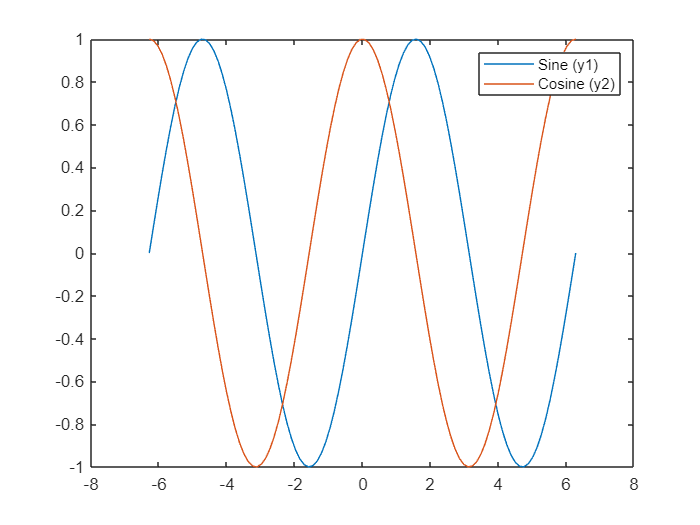

x = linspace(-2*pi,2*pi); %Creates uniformly spaced array of values in range -2pi to 2pi
y1 = sin(x);
y2 = cos(x);

plot(x,y1,x,y2) %Plots the functions defined above
legend('Sine (y1)', 'Cosine (y2)'); %Defining a legend, syntax in the same order of plotting

## Defining the graph parameters such as color,width markers etc

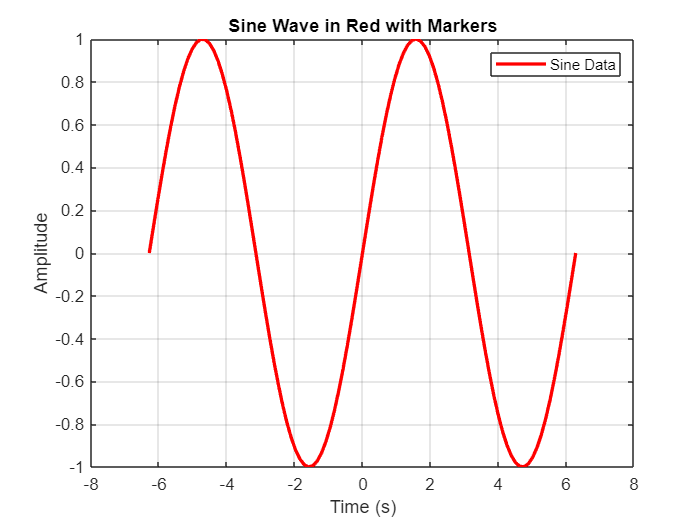

plot(x, y1, 'r-', 'LineWidth', 2, 'MarkerSize', 6);
xlabel('Time (s)');
ylabel('Amplitude');

% Add a title:
title('Sine Wave in Red with Markers');

% Add a legend:
legend('Sine Data');

% Turn on grid (optional):
grid on;

## Logarithms

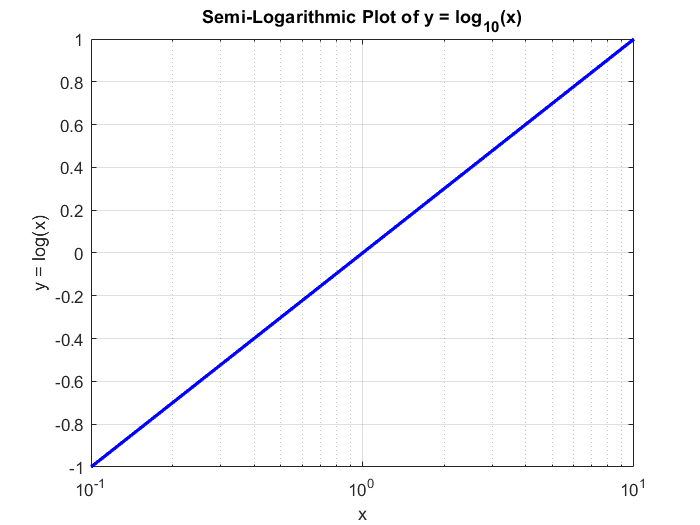

%------------log plots-------------
% MATLAB Code for a Logarithmic Plot

% Define the range of x values using linspace
x_1 = linspace(0.1, 10, 100); % Generates 100 points between 0.1 and 10

% Define the function y = log(x)
y_5 = log10(x_1);

% Create the logarithmic plot
figure; % Open a new figure window
semilogx(x_1, y_5, 'b-', 'LineWidth', 2); % semilog x-axis plot with a blue line

% Add labels, title, and grid
xlabel('x');
ylabel('y = log(x)');
title('Semi-Logarithmic Plot of y = log_{10}(x)');
grid on; % Enable grid for better visualization
hold off

## Using For loop

% EASY WAY...
x1 = linspace(0,2*pi)

x1 =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099


y = sin(x1)

y =          0    0.0634    0.1266    0.1893    0.2511    0.3120    0.3717    0.4298    0.4862    0.5406    0.5929    0.6428    0.6901    0.7346    0.7761    0.8146    0.8497    0.8815    0.9096    0.9341    0.9549    0.9718    0.9848    0.9938    0.9989    0.9999    0.9969    0.9898    0.9788    0.9638    0.9450    0.9224    0.8960    0.8660    0.8326    0.7958    0.7557    0.7127    0.6668    0.6182    0.5671    0.5137    0.4582    0.4009    0.3420    0.2817    0.2203    0.1580    0.0951    0.0317


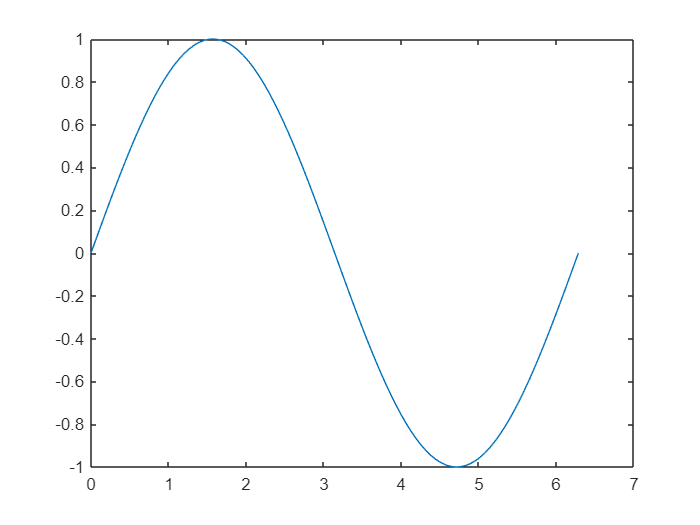

plot(x1,y)

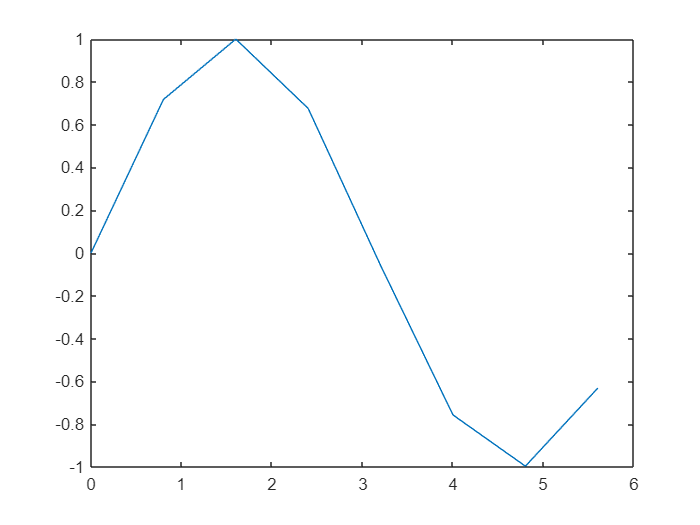


% Using For loops
x1 = 0:0.8:2*pi; %Modify to improve precision
Len = length(x1);
y1 = zeros(1,Len);
for i=1:Len
  y1(i) = sin(x1(i));  
end

plot(x1,y1);

## Sub-plots

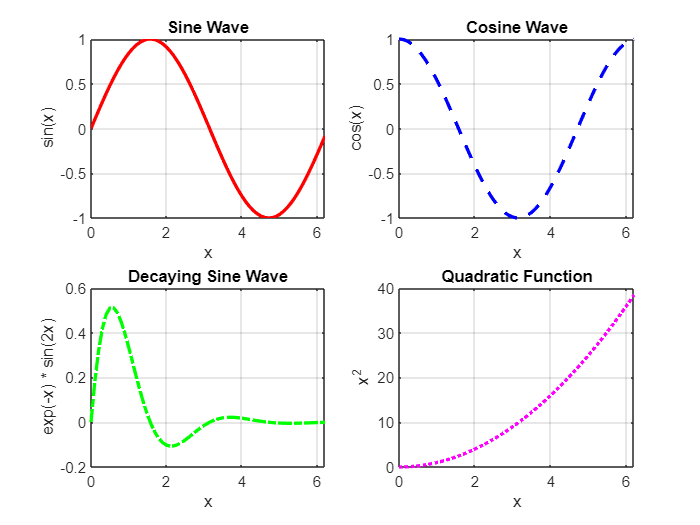

% Example Data
x = 0:0.1:2*pi; % x-values from 0 to 2π
y1 = sin(x);    % Sine wave
y2 = cos(x);    % Cosine wave
y3 = exp(-x).*sin(2*x); % Decaying sine wave
y4 = x.^2;      % Quadratic function

% --- Figure 1: Subplots ---
%figure(1); % Create a new figure window
%sgtitle('Figure 1: Subplots Example'); % Super title for all subplots

% Subplot 1: Sine Wave
subplot(2, 2, 1); % Divide the figure into 2x2 grid, plot in position 1
plot(x, y1, 'r', 'LineWidth', 2);
title('Sine Wave');
xlabel('x');
ylabel('sin(x)');
grid on;

% Subplot 2: Cosine Wave
subplot(2, 2, 2); % Position 2
plot(x, y2, 'b--', 'LineWidth', 2);
title('Cosine Wave');
xlabel('x');
ylabel('cos(x)');
grid on;

% Subplot 3: Decaying Sine Wave
subplot(2, 2, 3); % Position 3
plot(x, y3, 'g-.', 'LineWidth', 2);
title('Decaying Sine Wave');
xlabel('x');
ylabel('exp(-x) * sin(2x)');
grid on;

% Subplot 4: Quadratic Function
subplot(2, 2, 4); % Position 4
plot(x, y4, 'm:', 'LineWidth', 2);
title('Quadratic Function');
xlabel('x');
ylabel('x^2');
grid on;

% Use figure(Window number) in script to plot multiple graphs in seperate
% windos. For example figure(1) before plot code to plot first graph.
% figure(2) to plot on a seperate window. Note this would work mainly when
% you are using a normal script and not a live one.

## Laplace Transform

syms a t s; %Simulation variable to get expressions and not exact values
assume(a>=0) %Any constraints in a
f = exp(-a*t);
laplace(f);

% Laplace Transform of Heavyside function : u(t-a) 
transf=laplace(heaviside(t-a),t,s) %Syntax for heaviside and passing t,s

$$transf = \frac{{\mathrm{e}}^{-a\,s}}{s}$$

%%%%%% Inverse Laplace %%%%%%
syms s;
F = 1/s;
ilaplace(F) %inverse laplace of function

$$ans = 1$$